clear;
s = tf('s')

s =
 
  s
 
연속시간 전달 함수입니다.
모델 속성


A = [2, 3;
    -1, 4];
B = [0;
    1];
C = [1, 0];
D = 0

D = 0

sys = ss(A,B,C,D)

sys =
 
  A = 
       x1  x2
   x1   2   3
   x2  -1   4
 
  B = 
       u1
   x1   0
   x2   1
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
연속시간 상태공간 모델입니다.
모델 속성



rank(obsv(sys))

ans = 2

rank(ctrb(sys))

ans = 2


zeta = 0.8

zeta = 0.8000

wn = 10

wn = 10


poly = [1 2*0.8*10 10^2]    

poly =      1    16   100


root = roots(poly)

root =   -8.0000 + 6.0000i
  -8.0000 - 6.0000i



K = place(A,B,root)

K =    44.3333   22.0000


L = place(A',C',root)'

L =    22.0000
   59.0000



At = [A-B*K, B*K;
    zeros(size(A)), A-L*C];
Bt = [zeros(size(B));
    zeros(size(B))];
Ct = [zeros(size(C)) C];
sys_cl1 = ss(At,Bt,Ct,D)

sys_cl1 =
 
  A = 
           x1      x2      x3      x4
   x1       2       3       0       0
   x2  -45.33     -18   44.33      22
   x3       0       0     -20       3
   x4       0       0     -60       4
 
  B = 
       u1
   x1   0
   x2   0
   x3   0
   x4   0
 
  C = 
       x1  x2  x3  x4
   y1   0   0   1   0
 
  D = 
       u1
   y1   0
 
연속시간 상태공간 모델입니다.



t = 0:0.01:2;
u = zeros(size(t))

u =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x0 = [0.01 0]

x0 =     0.0100         0


lsim(sys_cl1,u,t,[x0 x0])
hold on
sys_cl2 = ss(A-B*K,B,C,D)

sys_cl2 =
 
  A = 
           x1      x2
   x1       2       3
   x2  -45.33     -18
 
  B = 
       u1
   x1   0
   x2   1
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
연속시간 상태공간 모델입니다.
모델 속성


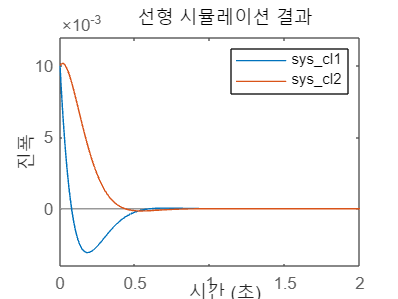

lsim(sys_cl2,u,t,x0)
hold off
legend

error1 = ss([A-L*C],[0; 0],[1,0],0)

error1 =
 
  A = 
        x1   x2
   x1  -20    3
   x2  -60    4
 
  B = 
       u1
   x1   0
   x2   0
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
연속시간 상태공간 모델입니다.
모델 속성


error2 = ss([A-L*C],[0; 0],[0,1],0)

error2 =
 
  A = 
        x1   x2
   x1  -20    3
   x2  -60    4
 
  B = 
       u1
   x1   0
   x2   0
 
  C = 
       x1  x2
   y1   0   1
 
  D = 
       u1
   y1   0
 
연속시간 상태공간 모델입니다.
모델 속성


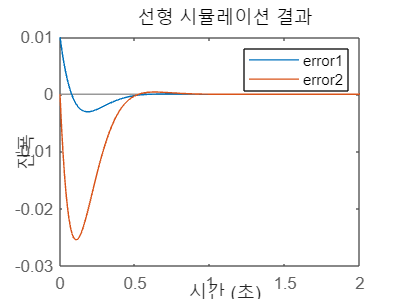

lsim(error1,u,t,x0)
hold on
lsim(error2,u,t,x0)
hold off
legend

clear;
A = [0 1 0 0;
    0 0 -1 0;
    0 0 0 1;
    0 0 100 0];
B = [0;
    0.1;z
    0;
    1];
C = [1 0 0 0];
D = 0;
sys = ss(A,B,C,D)

sys =
 
  A = 
        x1   x2   x3   x4
   x1    0    1    0    0
   x2    0    0   -1    0
   x3    0    0    0    1
   x4    0    0  100    0
 
  B = 
        u1
   x1    0
   x2  0.1
   x3    0
   x4    1
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
 
  D = 
       u1
   y1   0
 
연속시간 상태공간 모델입니다.


rank(obsv(sys))

ans = 4

rank(ctrb(sys))

ans = 4


zeta = 0.8;
wn = 0.5;

poly = [1 2*zeta*wn wn^2]

poly =     1.0000    0.8000    0.2500


root = roots(poly)

root =   -0.4000 + 0.3000i
  -0.4000 - 0.3000i


r1 = root(1)

r1 = -0.4000 + 0.3000i

r2 = root(2)

r2 = -0.4000 - 0.3000i

r3 = r1*20

r3 = -8.0000 + 6.0000i

r4 = r2*20

r4 = -8.0000 - 6.0000i

p1 = [r1;r2;r3;r4]

p1 =   -0.4000 + 0.3000i
  -0.4000 - 0.3000i
  -8.0000 + 6.0000i
  -8.0000 - 6.0000i


K = place(A,B,p1)

K =    -2.2727   -7.6364  213.2773   17.5636


p2 = [r3;r4;r3*2;r4*2]

p2 =   -8.0000 + 6.0000i
  -8.0000 - 6.0000i
 -16.0000 +12.0000i
 -16.0000 -12.0000i


L = place(A',C',p2)'

L = 1.0e+05 *

    0.0005
    0.0111
   -0.1440
   -1.5120



C_new = [0 0 1 0] % to see pendulum angle

C_new =      0     0     1     0



sys_cl = ss(A-B*K,B,C_new,D)

sys_cl =
 
  A = 
           x1      x2      x3      x4
   x1       0       1       0       0
   x2  0.2273  0.7636  -22.33  -1.756
   x3       0       0       0       1
   x4   2.273   7.636  -113.3  -17.56
 
  B = 
        u1
   x1    0
   x2  0.1
   x3    0
   x4    1
 
  C = 
       x1  x2  x3  x4
   y1   0   0   1   0
 
  D = 
       u1
   y1   0
 
연속시간 상태공간 모델입니다.


t = 0:0.01:5;
u = zeros(size(t));
x0 = [0, 0, 5.72*pi/180, 0]

x0 =          0         0    0.0998         0



lsim(sys_cl,u,t,x0)
hold on;

At = [A-B*K, B*K;
    zeros(size(A)), A-L*C]

At = 1.0e+05 *

         0    0.0000         0         0         0         0         0         0
    0.0000    0.0000   -0.0002   -0.0000   -0.0000   -0.0000    0.0002    0.0000
         0         0         0    0.0000         0         0         0         0
    0.0000    0.0001   -0.0011   -0.0002   -0.0000   -0.0001    0.0021    0.0002
         0         0         0         0   -0.0005    0.0000         0         0
         0         0         0         0   -0.0111         0   -0.0000         0
         0         0         0         0    0.1440         0         0    0.0000
         0         0         0         0    1.5120         0    0.0010         0


Bt = [zeros(size(B));
    zeros(size(B))]

Bt =      0
     0
     0
     0
     0
     0
     0
     0


Ct = [C_new zeros(size(C_new))]

Ct =      0     0     1     0     0     0     0     0


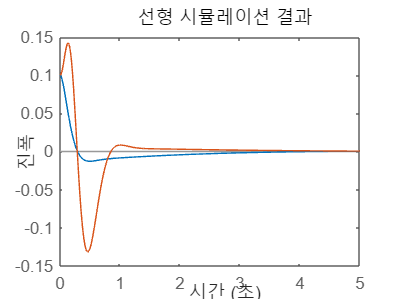


sys_cl = ss(At,Bt,Ct,D);
lsim(sys_cl, u, t, [x0 x0])
hold off;

At = [A-B*K, B*K;
    zeros(size(A)), A-L*C]

At = 1.0e+05 *

         0    0.0000         0         0         0         0         0         0
    0.0000    0.0000   -0.0002   -0.0000   -0.0000   -0.0000    0.0002    0.0000
         0         0         0    0.0000         0         0         0         0
    0.0000    0.0001   -0.0011   -0.0002   -0.0000   -0.0001    0.0021    0.0002
         0         0         0         0   -0.0005    0.0000         0         0
         0         0         0         0   -0.0111         0   -0.0000         0
         0         0         0         0    0.1440         0         0    0.0000
         0         0         0         0    1.5120         0    0.0010         0


Bt = [B;
    zeros(size(B))]

Bt =          0
    0.1000
         0
    1.0000
         0
         0
         0
         0


Ct = [C zeros(size(C))]

Ct =      1     0     0     0     0     0     0     0


sys_cl = ss(At,Bt,Ct,D)

sys_cl =
 
  A = 
              x1         x2         x3         x4         x5         x6         x7         x8
   x1          0          1          0          0          0          0          0          0
   x2     0.2273     0.7636     -22.33     -1.756    -0.2273    -0.7636      21.33      1.756
   x3          0          0          0          1          0          0          0          0
   x4      2.273      7.636     -113.3     -17.56     -2.273     -7.636      213.3      17.56
   x5          0          0          0          0        -48          1          0          0
   x6          0          0          0          0      -1112          0         -1          0
   x7          0          0          0          0   1.44e+04          0          0          1
   x8          0          0          0          0  1.512e+05          0        100          0
 
  B = 
        u1
   x1    0
   x2  0.1
   x3    0
   x4    1
   x5    0
   x6    0
   x7    0
   x8    0
 
  C = 
       x1  x2  x3  

N = 1/dcgain(sys_cl)

N = -2.2727

Bt = [N*B;
    zeros(size(B))]

Bt =          0
   -0.2273
         0
   -2.2727
         0
         0
         0
         0


sys_cl = ss(At,Bt,Ct,D);
t = 0:0.01:20;
u = ones(size(t));
x0 = [0, 0, 0, 0]

x0 =      0     0     0     0


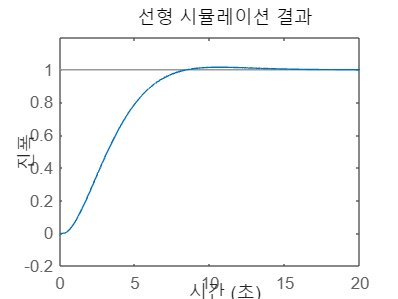

lsim(sys_cl, u, t, [x0 x0])

clear;
A = [0 1 0 0;
    0 0 -1 0;
    0 0 0 1;
    0 0 100 0];
B = [0;
    0.1;
    0;
    1];
C = [1 0 0 0];
D = 0;
sys = ss(A,B,C,D)

sys =
 
  A = 
        x1   x2   x3   x4
   x1    0    1    0    0
   x2    0    0   -1    0
   x3    0    0    0    1
   x4    0    0  100    0
 
  B = 
        u1
   x1    0
   x2  0.1
   x3    0
   x4    1
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
 
  D = 
       u1
   y1   0
 
연속시간 상태공간 모델입니다.


rank(obsv(sys))

ans = 4

rank(ctrb(sys))

ans = 4


zeta = 0.8;
wn = 0.5;

poly1 = [1 2*zeta*wn wn^2]

poly1 =     1.0000    0.8000    0.2500


root = roots(poly1)

root =   -0.4000 + 0.3000i
  -0.4000 - 0.3000i


r1 = root(1)

r1 = -0.4000 + 0.3000i

r2 = root(2)

r2 = -0.4000 - 0.3000i

r3 = r1*20

r3 = -8.0000 + 6.0000i

r4 = r2*20

r4 = -8.0000 - 6.0000i

p1 = [r1;r2;r3;r4]

p1 =   -0.4000 + 0.3000i
  -0.4000 - 0.3000i
  -8.0000 + 6.0000i
  -8.0000 - 6.0000i


K = place(A,B,p1)

K =    -2.2727   -7.6364  213.2773   17.5636


p2 = [r3;r4;r3*2;r4*2]

p2 =   -8.0000 + 6.0000i
  -8.0000 - 6.0000i
 -16.0000 +12.0000i
 -16.0000 -12.0000i


L = place(A',C',p2)'

L = 1.0e+05 *

    0.0005
    0.0111
   -0.1440
   -1.5120



C_new = [0 0 1 0]

C_new =      0     0     1     0



At = [A-B*K, B*K;
    zeros(size(A)), A-L*C];
Bt = [zeros(size(B));
    zeros(size(B))];
Ct = [C_new zeros(size(C))]

Ct =      0     0     1     0     0     0     0     0



sys_cl = ss(At,Bt,Ct,D)

sys_cl =
 
  A = 
              x1         x2         x3         x4         x5         x6         x7         x8
   x1          0          1          0          0          0          0          0          0
   x2     0.2273     0.7636     -22.33     -1.756    -0.2273    -0.7636      21.33      1.756
   x3          0          0          0          1          0          0          0          0
   x4      2.273      7.636     -113.3     -17.56     -2.273     -7.636      213.3      17.56
   x5          0          0          0          0        -48          1          0          0
   x6          0          0          0          0      -1112          0         -1          0
   x7          0          0          0          0   1.44e+04          0          0          1
   x8          0          0          0          0  1.512e+05          0        100          0
 
  B = 
       u1
   x1   0
   x2   0
   x3   0
   x4   0
   x5   0
   x6   0
   x7   0
   x8   0
 
  C = 
       x1  x2  x3  x4  x5  x

t = 0:0.01:5

t =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


u = zeros(size(t))

u =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x0 = [0, 0, 5.72*pi/180, 0]

x0 =          0         0    0.0998         0


sys1 = ss(A-B*K,B,C_new,D)

sys1 =
 
  A = 
           x1      x2      x3      x4
   x1       0       1       0       0
   x2  0.2273  0.7636  -22.33  -1.756
   x3       0       0       0       1
   x4   2.273   7.636  -113.3  -17.56
 
  B = 
        u1
   x1    0
   x2  0.1
   x3    0
   x4    1
 
  C = 
       x1  x2  x3  x4
   y1   0   0   1   0
 
  D = 
       u1
   y1   0
 
연속시간 상태공간 모델입니다.


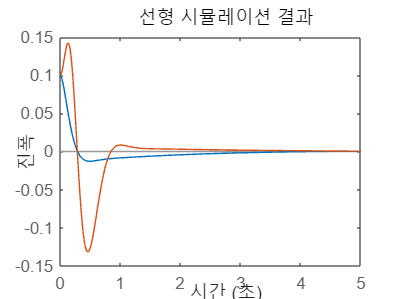

lsim(sys1,u,t,x0)
hold on
lsim(sys_cl,u,t,[x0 x0])
hold off

clear;
A = [0 1 0 0;
    0 0 -1 0;
    0 0 0 1;
    0 0 100 0];
B = [0;
    0.1;
    0;
    1];
C = [1 0 0 0];
D = 0;
sys = ss(A,B,C,D)

sys =
 
  A = 
        x1   x2   x3   x4
   x1    0    1    0    0
   x2    0    0   -1    0
   x3    0    0    0    1
   x4    0    0  100    0
 
  B = 
        u1
   x1    0
   x2  0.1
   x3    0
   x4    1
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
 
  D = 
       u1
   y1   0
 
연속시간 상태공간 모델입니다.


rank(obsv(sys))

ans = 4

rank(ctrb(sys))

ans = 4


zeta = 0.8;
wn = 0.5;

poly1 = [1 2*zeta*wn wn^2]

poly1 =     1.0000    0.8000    0.2500


root = roots(poly1)

root =   -0.4000 + 0.3000i
  -0.4000 - 0.3000i


r1 = root(1)

r1 = -0.4000 + 0.3000i

r2 = root(2)

r2 = -0.4000 - 0.3000i

r3 = r1*20

r3 = -8.0000 + 6.0000i

r4 = r2*20

r4 = -8.0000 - 6.0000i

p1 = [r1;r2;r3;r4]

p1 =   -0.4000 + 0.3000i
  -0.4000 - 0.3000i
  -8.0000 + 6.0000i
  -8.0000 - 6.0000i


K = place(A,B,p1)

K =    -2.2727   -7.6364  213.2773   17.5636


p2 = [r3;r4;r3*2;r4*2]

p2 =   -8.0000 + 6.0000i
  -8.0000 - 6.0000i
 -16.0000 +12.0000i
 -16.0000 -12.0000i


L = place(A',C',p2)'

L = 1.0e+05 *

    0.0005
    0.0111
   -0.1440
   -1.5120



At = [A-B*K, B*K;
    zeros(size(A)), A-L*C];
Bt = [B;
    zeros(size(B))]

Bt =          0
    0.1000
         0
    1.0000
         0
         0
         0
         0


Ct = [C zeros(size(C))];

sys_cl = ss(At,Bt,Ct,D)

sys_cl =
 
  A = 
              x1         x2         x3         x4         x5         x6         x7         x8
   x1          0          1          0          0          0          0          0          0
   x2     0.2273     0.7636     -22.33     -1.756    -0.2273    -0.7636      21.33      1.756
   x3          0          0          0          1          0          0          0          0
   x4      2.273      7.636     -113.3     -17.56     -2.273     -7.636      213.3      17.56
   x5          0          0          0          0        -48          1          0          0
   x6          0          0          0          0      -1112          0         -1          0
   x7          0          0          0          0   1.44e+04          0          0          1
   x8          0          0          0          0  1.512e+05          0        100          0
 
  B = 
        u1
   x1    0
   x2  0.1
   x3    0
   x4    1
   x5    0
   x6    0
   x7    0
   x8    0
 
  C = 
       x1  x2  x3  

N = 1/dcgain(sys_cl)

N = -2.2727

Bt = [N*B;
    zeros(size(B))]

Bt =          0
   -0.2273
         0
   -2.2727
         0
         0
         0
         0


sys_cl = ss(At,Bt,Ct,D)

sys_cl =
 
  A = 
              x1         x2         x3         x4         x5         x6         x7         x8
   x1          0          1          0          0          0          0          0          0
   x2     0.2273     0.7636     -22.33     -1.756    -0.2273    -0.7636      21.33      1.756
   x3          0          0          0          1          0          0          0          0
   x4      2.273      7.636     -113.3     -17.56     -2.273     -7.636      213.3      17.56
   x5          0          0          0          0        -48          1          0          0
   x6          0          0          0          0      -1112          0         -1          0
   x7          0          0          0          0   1.44e+04          0          0          1
   x8          0          0          0          0  1.512e+05          0        100          0
 
  B = 
            u1
   x1        0
   x2  -0.2273
   x3        0
   x4   -2.273
   x5        0
   x6        0
   x7        0
   x8  

t = 0:0.01:20

t =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


u = ones(size(t))

u =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


x0 = [0, 0, 0, 0]

x0 =      0     0     0     0


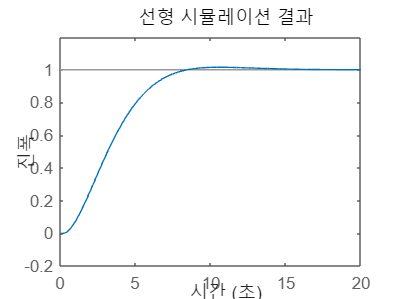

lsim(sys_cl,u,t,[x0 x0])